# Part 3

In this part, we are required to compress a text file using *Huffman* codes.

First, We need to acquire the text. You can select a text file by pressing the browse button:

 
textFromFile = false;
[file , path] = uigetfile ('*.txt');

if(~file)
    disp('No file was selected.');
else
    disp(strcat("Selected file: ", file));
    originalText = fileread (strcat(path,file));
    textFromFile = true;
end

Selected file: lorem.txt


Selected text:

disp(originalText);

Lorem ipsum dolor sit amet, consectetur adipiscing elit. Pellentesque congue gravida leo, at euismod ligula fringilla vitae. Proin lobortis eleifend vestibulum. Donec eu vulputate velit. Donec vehicula quam nec tellus semper, at sollicitudin ex suscipit. Cras nisi nunc, porttitor sit amet tortor non, placerat dictum lorem. Maecenas volutpat metus in malesuada fringilla. Maecenas pulvinar eros in tempus eleifend. Phasellus vel rutrum ligula, ac porta massa. Vestibulum convallis, tellus non mollis luctus, arcu dolor fermentum purus, eget semper quam eros nec lacus. Maecenas consectetur, velit ac vestibulum facilisis, dolor ex ullamcorper diam, a tristique quam lorem sed metus. Nam blandit augue nunc, vitae mattis erat condimentum facilisis. Nullam porttitor, tortor accumsan lacinia efficitur, ex augue posuere nunc, a ultricies neque lorem quis arcu. Aliquam tempor enim quis suscipit porttitor. In hac habitasse platea dictumst. Mauris vehicula at justo vitae venenatis.

Proin interdum por

Our file should consist of these characters only:

charList = char(strcat(char(65:90),char(97:122), char(49:57), ",. "))

charList = 'ABCDEFGHIJKLMNOPQRSTUVWXYZabcdefghijklmnopqrstuvwxyz123456789,. '

We now extract the character data from the file and find its *Probability Mass Function, *after removing all invalid characters:

originalText(~ismember(originalText, charList)) = '';
sortedText = sort(originalText);
[labels, charPMF] = PMF(sortedText);
pmfTable = table(transpose(labels), transpose(charPMF), 'VariableNames', {'Character', 'Probability'});
disp(pmfTable)

    Character    Probability
    _________    ___________

                    0.14225 
        ,          0.014619 
        .          0.017712 
        A        0.00056227 
        C         0.0014057 
        D          0.001968 
        F         0.0014057 
        I         0.0011245 
        L        0.00028114 
        M         0.0022491 
        N         0.0025302 
        P         0.0036548 
        Q        0.00084341 
        S        0.00084341 
        V        0.00084341 
        a          0.072533 
        b          0.006185 
        c          0.037391 
        d          0.019961 
        e          0.093899 
        f         0.0075907 
        g          0.010964 
        h          0.006185 
        i          0.078156 
        j        0.00056227 
        l          0.050323 
        m          0.039921 
        n          0.048074 
        o          0.036267 
        p          0.018555 
   

## Huffman Encoding

We can now use the built in function to generate a Huffman code for our file:

% The huffmandict function can't deal with the symbols as chars. We need to
% cast them into doubles.

%%% TODO: Fix Display

symbols = double(labels);
dict = huffmandict(symbols, charPMF);
huffTable = cell2table(dict);
huffTable.Properties.VariableNames = {'Character', 'Codeword'};
huffTable.Character = char(huffTable.Character);

disp(huffTable)

    Character            Codeword         
    _________    _________________________

                 {[                0 1 1]}
        ,        {[          1 0 0 1 1 1]}
        .        {[          1 0 0 1 0 0]}
        A        {[1 1 1 1 0 1 1 1 0 0 0]}
        C        {[    1 1 1 1 0 0 0 1 1]}
        D        {[    1 0 0 1 0 1 0 0 1]}
        F        {[    1 1 1 1 0 0 0 1 0]}
        I        {[  1 1 1 1 0 0 0 0 0 0]}
        L        {[1 1 1 1 0 1 1 1 0 0 1]}
        M        {[    1 0 0 1 0 1 0 0 0]}
        N        {[      1 1 1 1 0 1 1 0]}
        P        {[      1 0 0 1 0 1 0 1]}
        Q        {[  1 1 1 1 0 0 0 0 1 1]}
        S        {[  1 1 1 1 0 0 0 0 1 0]}
        V        {[  1 1 1 1 0 0 0 0 0 1]}
        a        {[              0 1 0 0]}
        b        {[        1 1 1 1 0 1 0]}
        c        {[            0 0 1 0 0]}
        d        {[          0 0 0 0 1 0]}
        e        {[         

Now, we are ready to encode our text file:

encoded = huffmanenco(originalText, dict);
huffman = num2str(encoded);
huffman = strrep(huffman,' ','');
ascii = dec2bin(originalText);
ascii = reshape(ascii',1,[]);

codeTable = cell2table({ascii; huffman});
codeTable.Properties.VariableNames = {'Encoded File'};
codeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(codeTable)

We know find the compression ratio:

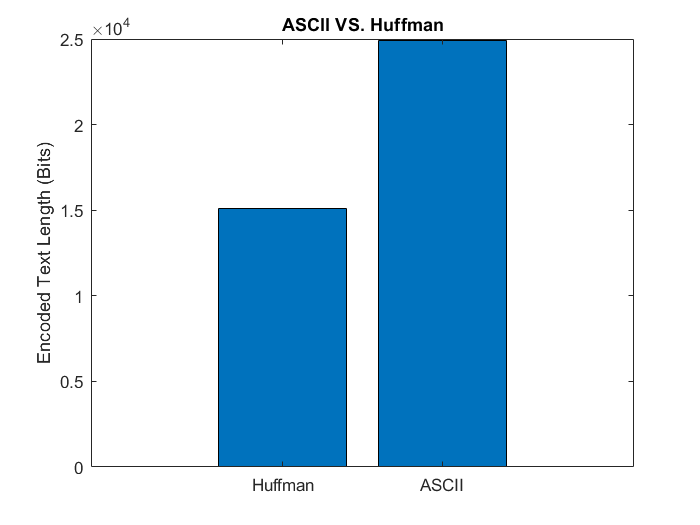

huffLen = length(huffman);
asciiLen = length(ascii);
lenArr = [huffLen asciiLen];
gra = bar(lenArr);
xticklabels({'Huffman', 'ASCII'});
title('ASCII VS. Huffman');
ylabel('Encoded Text Length (Bits)');

We can now calculate the compression ratio by applying the formula:


$$\eta =\frac{l\left(\mathrm{ASCII}\right)-l\left(\mathrm{Huffman}\right)}{l\left(\mathrm{ASCII}\right)}\times 100%$$


compRatio = ((asciiLen - huffLen)/asciiLen) * 100;
fprintf("η = %f %%", compRatio)

η = 39.342945 %

## Decoding

We now decode both the ASCII and the Huffman files to check for errors. We expect none due to the one-to-one mapping in both ASCII and Huffman:

decodedHuff = char(huffmandeco(encoded, dict));
decodedASCII = zeros(1, asciiLen);

for i = 1:7:asciiLen-6
    % We need to decode each 7 bits into a single character
    
    letterBits = extractBetween(ascii, i, i+6);
    letter = char(bin2dec(letterBits));
    decodedASCII = strcat(decodedASCII, letter);
end


decodeTable = cell2table({decodedASCII; decodedHuff});
decodeTable.Properties.VariableNames = {'Decoded File'};
decodeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(decodeTable);


% And now, we compare the decoded text with the original text:

if(strcmp(decodedHuff, originalText))
    disp("Huffman codes are error free as expected.")
end

Huffman codes are error free as expected.



if(strcmp(decodedASCII, originalText))
    disp("ASCII codes are error free as expected.")
end

We now output the Huffman decoded file for further inspection:

 
fid = fopen(strcat(path,"huffman.txt"),'w+');
fprintf(fid, decodedHuff);
fclose(fid);

## Comments

- We notice that a worst case for our compression ratio exists $\approx 40%$

- Huffman coding is a lossless coding method, which by definition means it's error free.

- ASCII codes are made for computers to represent text, not for compression. We have 64 characters in our character list, which means we need only $\log_2 \left(64\right)=6\;\mathrm{Bits}$ to represent each charachter, not $7\;\mathrm{Bits}$.

## Functions

function  [uniqueChars, pmfCharArr] = PMF(text)
            % Returns the probability of each charachter in an array
            
            textLen = length(text);
            uniqueChars = unique(text);
            uniques = length(uniqueChars);
            pmfCharArr = zeros(1, uniques);
            
            for idx = 1:uniques
                pmfCharArr(idx) = sum(text == uniqueChars(idx)) / textLen ;
            end
 end